# TP 5 - Motion analysis - Lucas and Kanade

## Question 1

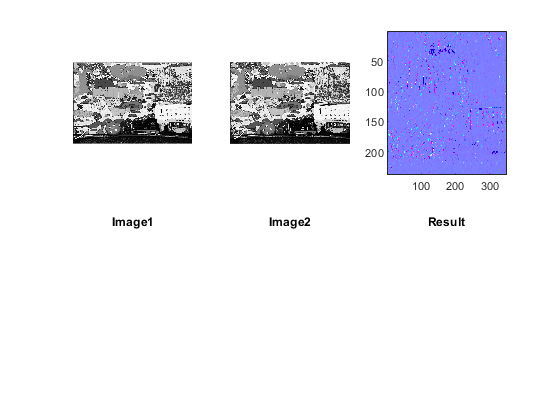

clear all
close all
clc
warning off;
figure();
subplot(2,3,1);
im1=imread('TP06I01.bmp');
imshow(im1)
subplot(2,3,2);
im2=imread('TP06I02.bmp');
imshow(im2)
subplot(2,3,3);
im1=double(im1);
im2=double(im2);
[vx,vy,mask] = syst(im1,im2,0,3);
k=10;
img = nan(238,350,3);
img(:,:,1) = 128+k*vx;
img(:,:,2) = 128+k*vy;
img(:,:,3) = 255*ones(238,350);
image(uint8(img))



[x,y]=size(im1);
for i=2:x-1
    for j=2:y-1
        add1=(im1(i-1,j-1)-im1(i,j-1))^2;
        add2=(im1(i,j-1)-im1(i+1,j-1))^2;
        add3=(im1(i-1,j)-im1(i,j))^2;
        add4=(im1(i,j)-im1(i+1,j))^2;
        add5=(im1(i-1,j+1)-im1(i,j+1))^2;
        add6=(im1(i,j+1)-im1(i+1,j+1))^2;
        dx(i,j)=add1+add2+add3+add4+add5+add6;
        
        add1=(im1(i-1,j-1)-im1(i-1,j))^2;
        add2=(im1(i-1,j)-im1(i-1,j+1))^2;
        add3=(im1(i,j-1)-im1(i,j))^2;
        add4=(im1(i,j)-im1(i,j+1))^2;
        add5=(im1(i+1,j-1)-im1(i+1,j))^2;
        add6=(im1(i+1,j)-im1(i+1,j+1))^2;
        dy(i,j)=add1+add2+add3+add4+add5+add6;
        
        add1=im1(i-1,j-1)-im1(i,j);
        add2=im1(i,j)-im1(i+1,j+1);
        add3=im1(i-1,j)-im1(i,j+1);
        add4=im1(i,j-1)-im1(i+1,j);
        dxy(i,j)=add1+add2+add3+add4;
        
    end
end

subplot(2,3,4);
title("Image1");
axis off;
subplot(2,3,5);
title("Image2");
axis off;
subplot(2,3,6);
title("Result");
axis off;

## Question 2

seuil = 5000

seuil = 5000

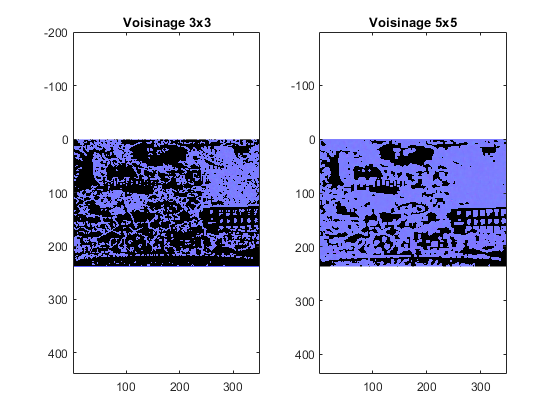

voisinage = 3; %3,5,7,...
[vx,vy,mask] = syst(im1,im2,seuil,voisinage);
img = nan(240-(voisinage-1),352-(voisinage-1),3);
img(:,:,1) = (128+k*vx).*mask;
img(:,:,2) = (128+k*vy).*mask;
img(:,:,3) = (255*ones(240-(voisinage-1),352-(voisinage-1))).*mask;
figure()
subplot(1,2,1)
image(uint8(img))
axis equal;
title("Voisinage 3x3")

voisinage = 5; %3,5,7,...
[vx,vy,mask] = syst(im1,im2,seuil,voisinage);
img = nan(240-(voisinage-1),352-(voisinage-1),3);
img(:,:,1) = (128+k*vx).*mask;
img(:,:,2) = (128+k*vy).*mask;
img(:,:,3) = (255*ones(240-(voisinage-1),352-(voisinage-1))).*mask;
subplot(1,2,2)
image(uint8(img))
axis equal;
title("Voisinage 5x5")

Les valeurs propres sont croissantes avec la taille du voisinage choisie, il faut donc faire croitre le seuil avec la taille du voisinage.